# Perform Satellite Access Analysis

This example demonstrates how to set up a visibility access analysis between one satellite and one ground station.  The example calculates the times over the course of a day when the satellite can see the ground station.

Copyright 2022-2023 The MathWorks, Inc.

## Create Satellite Scenario

Use `satelliteScenario` to create a satellite scenario named `sc`.  Use `datetime` to define the start time and stop time of the scenario.  Set the sample time to 60 seconds.  To learn the `satelliteScenario` syntax, type `doc satelliteScenario` at the MATLAB® command line.

startTime = datetime(2020,8,19,20,55,0); % 19 August 2020 8:55 PM UTC, value-only argument
stopTime = startTime + days(1);          % 20 August 2020 8:55 PM UTC, value-only argument
sampleTime = 60;                         % seconds, value-only argument
sc = satelliteScenario(startTime,stopTime,sampleTime);

## Launch Satellite Scenario Viewer

Use `satelliteScenarioViewer` to launch a Satellite Scenario Viewer.

vwr = satelliteScenarioViewer(sc);

## Add Satellite to Scenario

Use `satellite` to add a satellite with variable name `sat` to the scenario `sc` by specifying its Keplerian orbital elements corresponding to the scenario start time.  Specify the name of the satellite as "Satellite", and the orbit propagator as "two-body-keplerian".  To learn the `satellite` syntax, type `doc satellite` at the MATLAB command line.

semiMajorAxis = 1e7;               % meters, value-only argument
eccentricity = 0.2;                % unitless, value-only argument
inclination = 0;                   % degrees, value-only argument
rightAscensionOfAscendingNode = 0; % degrees, value-only argument
argumentOfPeriapsis = 0;           % degrees, value-only argument
trueAnomaly = 0;                   % degrees, value-only argument
orbProp = "two-body-keplerian";    % name-value pair
satName = "Satellite";             % name-value pair
% Add the satellite with variable name sat.  Hint: Type "doc satellite" in
% the MATLAB Command Window, and see the "Syntax" section.
sat = satellite(sc, ...
  semiMajorAxis, ...
  eccentricity, ...
  inclination, ...
  rightAscensionOfAscendingNode, ...
  argumentOfPeriapsis, ...
  trueAnomaly, ...
  OrbitPropagator=orbProp, ...
  Name=satName);

When you are done with this section and you run it, you should see a Satellite Scenario Viewer that looks like this:

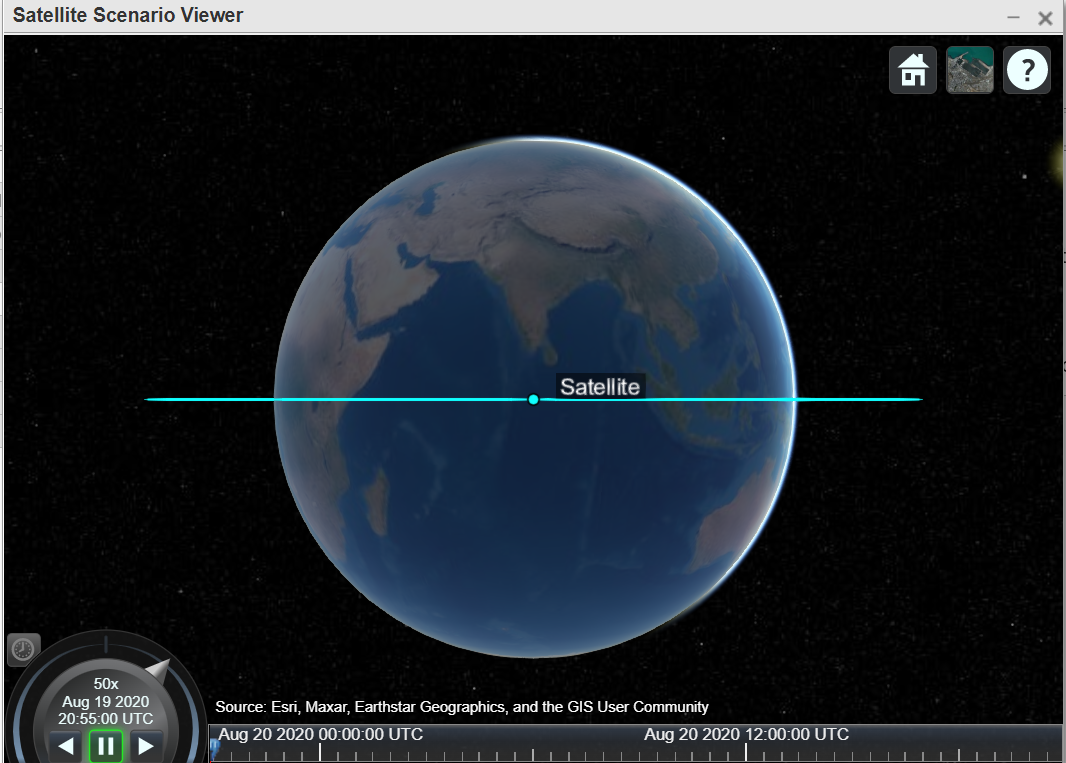

## Add Conical Sensor to Satellite

Use `conicalSensor` to add a camera with variable name `camera` to the satellite `sat`.  This sensor will determine visual access between the satellite and the ground station.  Define a viewing angle constraint on the sensor to model a realistic mechanical design.  Name the sensor "Camera".  Use `fieldOfView` to enable a field of view visualization.

Since the conical sensor is attached directly to the satellite, when the sensor slews to a target, the entire satellite slews to the target.  Although this is unrealistic in an actual satellite scenario, it simplifies the modeling without sacrificing any generality.

maxViewingAngle = 60;  % degrees in the range [0,180], name-value pair
csName = "Camera";     % name-value pair
% Add the conical sensor with variable name camera.  Hint:  Type "doc
% conicalSensor" in the MATLAB Command Window, and see the "Syntax"
% section.
camera = conicalSensor(sat, ...
  MaxViewAngle=maxViewingAngle, ...
  Name=csName);

% Enable field of view visualization of the conical sensor with variable
% name camera. Hint:  Type "doc fieldOfView" in the MATLAB Command Window,
% and see the "Syntax" section.
fieldOfView(camera);

When you are done with this section and you run it, you should see a Satellite Scenario Viewer that looks like this:

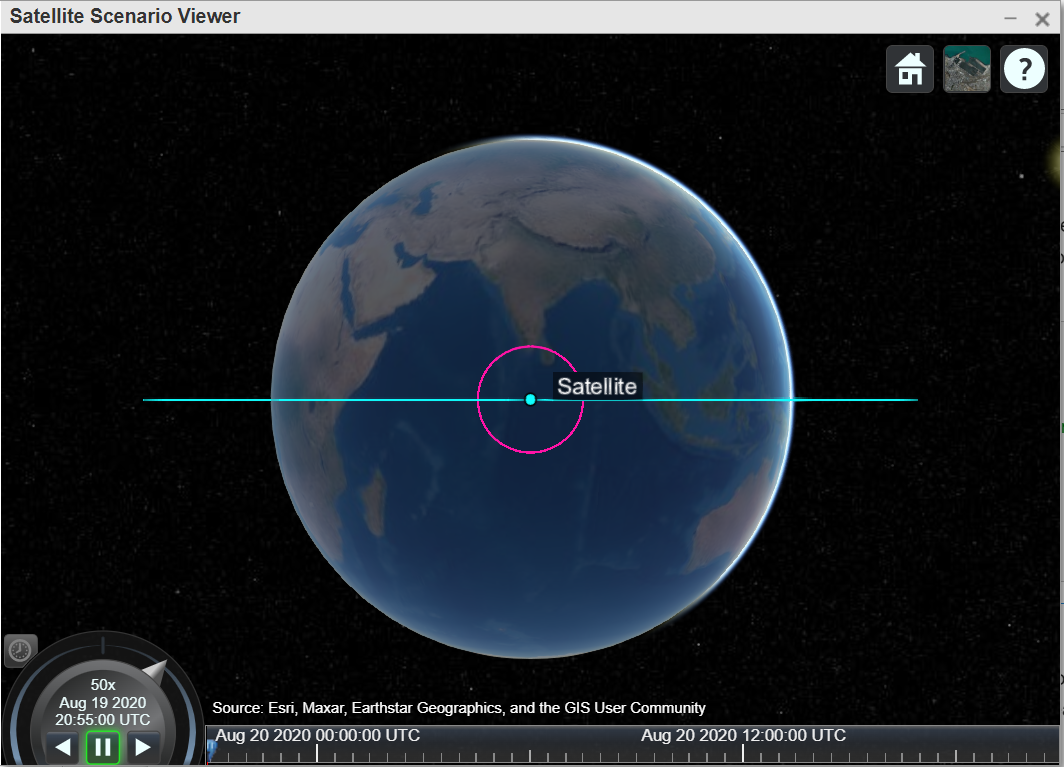

## Add Ground Station to Scenario

Use `groundStation` to add a ground station with variable name `gs` to the scenario `sc`.  Provide the latitude and longitude coordinates of the ground station.  Give the ground station a name called "Ground Station".  To learn the `groundStation` syntax, type `doc groundStation` at the MATLAB command line.

latitude = 12.9;  % degrees, value-only argument
longitude = 77.7; % degrees, value-only argument
gsName = "Ground Station";  % name-value pair
% Add ground station with variable name gs.  Hint:  Type "doc groundStation" in the
% MATLAB Command Window, and see the "Syntax" section.
gs = groundStation(sc, ...
  latitude, ...
  longitude, ...
  Name=gsName);

When you are done with this section and you run it, you should see a Satellite Scenario Viewer that looks like this:

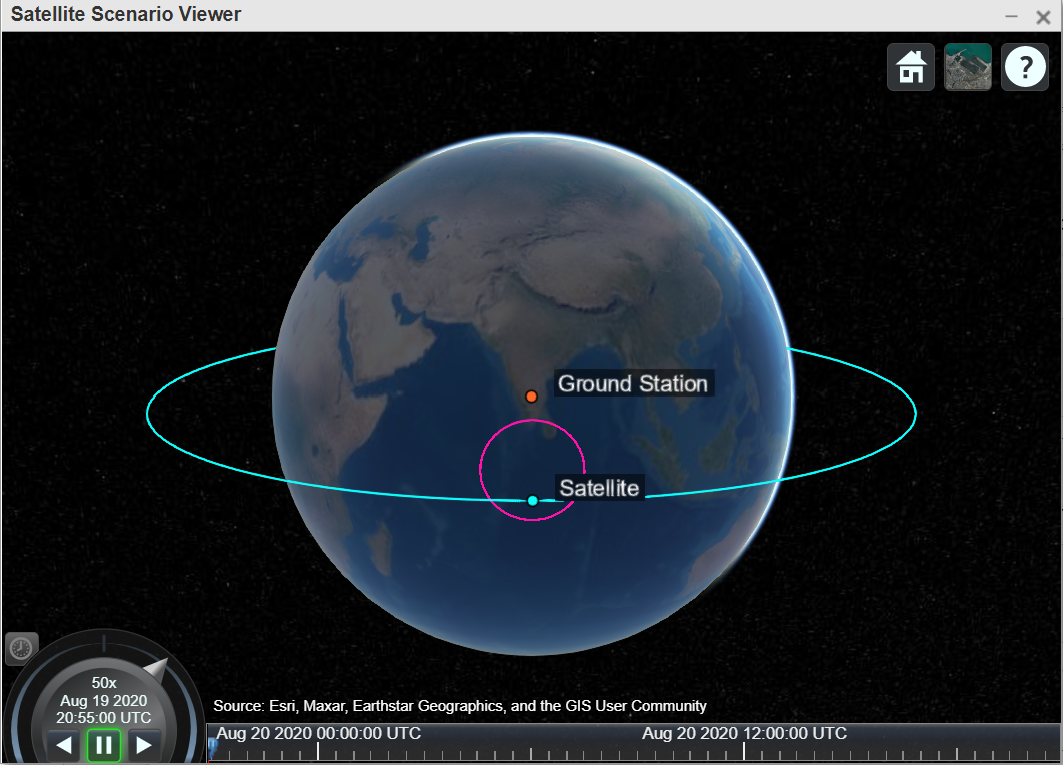

## Point Satellite at Ground Station

For maximum visibility from the satellite to the ground station, the satellite must point at the ground station, instead of nadir.  Use `pointAt` to point the satellite `sat` to the ground station `gs` for the duration of the simulation.  To learn the `pointAt` syntax, type `doc pointAt` at the MATLAB command line.

% Point the satellite sat at the ground station gs.  Hint:  Type "doc
% pointAt" in the MATLAB Command Window, and see the "Syntax" section.
% Use value-only arguments.
pointAt(sat,gs);

## Add Access Analysis and Visualize Scenario

Use `access` to set up a visibility access analysis with variable name `ac` from the satellite camera named `camera` to the ground station `gs`.

% Add access analysis with variable name ac.  Hint:  Type "doc access" in
% the MATLAB Command Window, and see the "Syntax" section.
% Use value-only arguments.
ac = access(camera,gs);

The Satellite Scenario Viewer automatically updates to display the entire scenario.  A line between the satellite and the ground station confirms that visual access is achieved at the start of the simulation.

When you are done with this section and you run it, you should see a Satellite Scenario Viewer that looks like this:

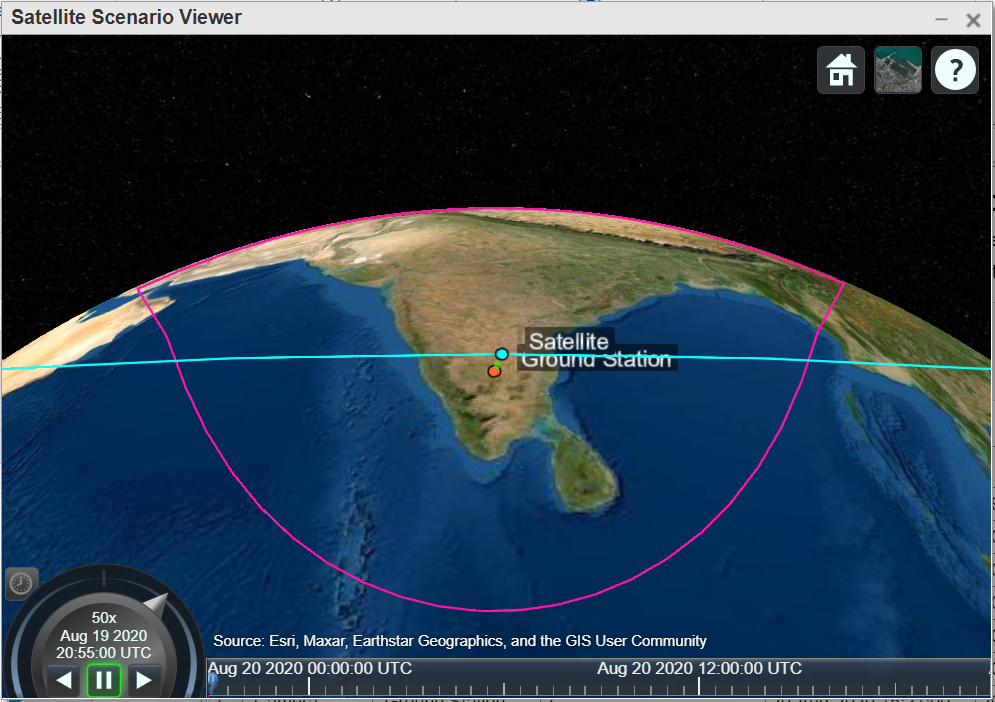

## Determine Times When Access Is Achieved, and Visualize Access

Use  `accessIntervals` to determine the times when visibility access is achieved.  The a`ccessIntervals` method outputs a table of the start and stop times of access that represent the intervals during which the satellite can see the ground station.

% Calculate access intervals.  Hint:  Type "doc accessIntervals" in the
% MATLAB Command Window, and see the "Syntax" section.
accessIntervals(ac)

ans = 8×8 table
     Source          Target         IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ________    ________________    ______________    ____________________    ____________________    ________    __________    ________

    "Camera"    "Ground Station"          1           19-Aug-2020 20:55:00    19-Aug-2020 21:07:00       720          1            1    
    "Camera"    "Ground Station"          2           19-Aug-2020 23:43:00    20-Aug-2020 00:15:00      1920          2            2    
    "Camera"    "Ground Station"          3           20-Aug-2020 02:42:00    20-Aug-2020 03:33:00      3060          3            3    
    "Camera"    "Ground St

When you are done with this section and you run it, you should have created an 8x8 table.

Use `play` to visualize the scenario simulation from its start time to stop time.  Set the playback speed to be 1000 times real time.  A line from the satellite to the ground station appears when visual access is achieved.

% Set the viewer camera (not satellite camera) position for better scenario
% viewing
camLat = latitude;   % camera latitude, deg
camLon = longitude;  % camera longitude, deg
camAlt = 2e7;        % camera altitude, m
campos(vwr,camLat,camLon,camAlt);

% Play the scenario sc.  Hint:  Type "doc satcom/play" in the MATLAB
% Command Window.  Look for "play" from Satellite Communications Toolbox,
% and see the "Syntax" section.
speedMultiplier = 1000;  % name-value pair
play(sc, ...
  PlaybackSpeedMultiplier=speedMultiplier);


When you are done with this section and you run it, you should see a Satellite Scenario Viewer that looks like this: